clear 

load('data/pts.mat');

c = 4;

r = 2;

tic()
 
[labels, peaks] = meanshift_opt2(data, r, c);

toc()

Elapsed time is 1.729769 seconds.


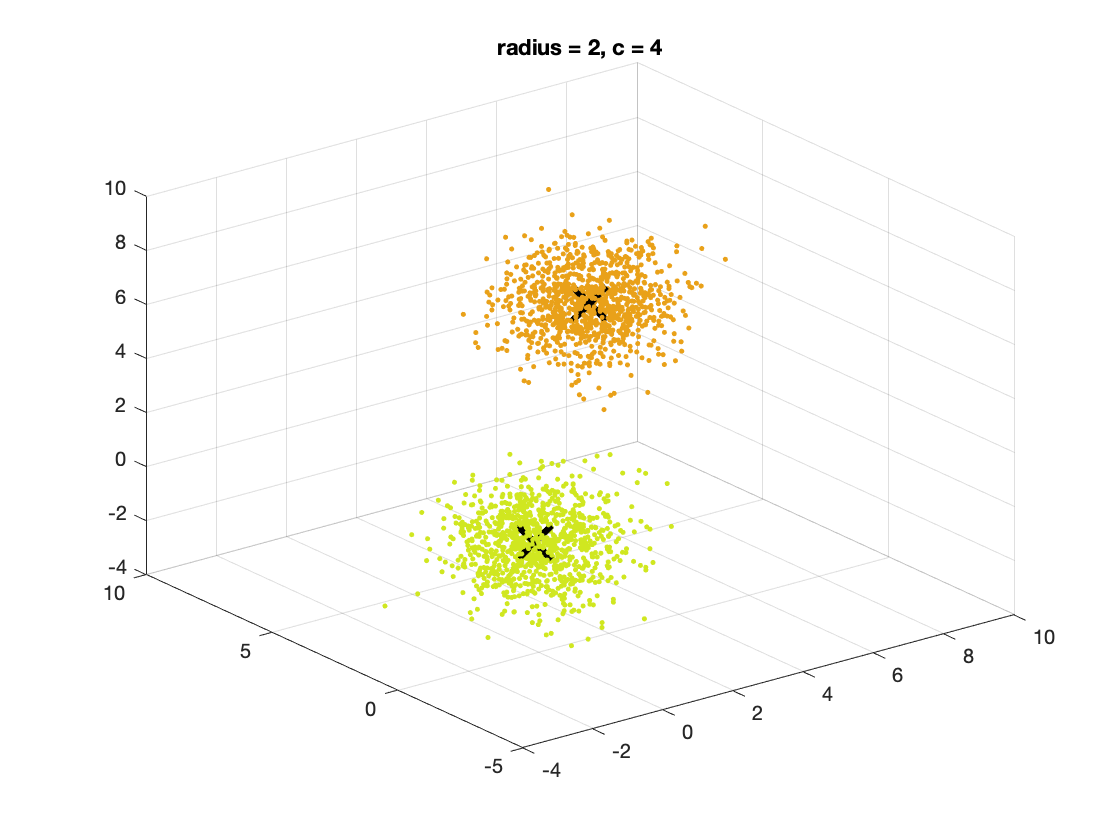


plot3dclusters( data, labels, peaks )
title(['radius = ',num2str(r),', c = ', num2str(c)]);

clear 

im = imread('img1.jpg');

r = 10;

c = 2;

feature_type = '5D';

tic()
 
[segmIm, labels, peaks, img] = imSegment(im, r, c, feature_type);

toc()

figure;
imshow(segmIm);
title(['radius = ',num2str(r),', c = ', num2str(c),', feature type = ', num2str(feature_type)]);

figure;
plot3dclustersRGB(im_flattened', labels, peaks )
title(['radius = ',num2str(r),', c = ', num2str(c),', feature type = ', num2str(feature_type)]);
